imds = imageDatastore('256_ObjectCategories', 'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

tbl = countEachLabel(imds);

minSetCount = min(tbl{:,2}); % determine the smallest amount of images in a category

% SETUP

% number of images from each class to be placed in the dataset
% use minSetCount to use the largest possible number
% numImgs = 60
% ratio of training data to test data
trainRatio = .6

trainRatio = 0.6000

% mini batch size: uses more memory when higher but can speed up stuff 
% 32 usually reasonable, decrease if running out of memory
miniSize = 30

miniSize = 30

% max epochs: default 30
maxEpoch = 15

maxEpoch = 15


% Use splitEachLabel method to trim the set.
% imds1 = splitEachLabel(imds, numImgs, 'randomized');
imds1 = imds

imds1 =   ImageDatastore with properties:

       Files: {
              'C:\Home CNN Fusion\256_ObjectCategories\001.ak47\001_0001.jpg';
              'C:\Home CNN Fusion\256_ObjectCategories\001.ak47\001_0002.jpg';
              'C:\Home CNN Fusion\256_ObjectCategories\001.ak47\001_0003.jpg'
               ... and 30604 more
              }
      Labels: [001; 001; 001 ... and 30604 more categorical]
    ReadSize: 1
     ReadFcn: @readDatastoreImage


% Notice that each set now has exactly the same number of images.
countEachLabel(imds1)

ans = 257×2 table
    Label    Count
    _____    _____

    001       98  
    002       97  
    003      151  
    004      127  
    005      148  
    006       90  
    007      106  
    008      232  
    009      102  
    010       94  
    011      278  
    012      216  
    013       98  
    014       86  
    015      122  
    016       91  


% Load pre-trained VGG19
net1 = vgg19();

% View the CNN architecture
net1.Layers

ans =   47x1 Layer array with layers:

     1   'input'     Image Input             224x224x3 images with 'zerocenter' normalization
     2   'conv1_1'   Convolution             64 3x3x3 convolutions with stride [1  1] and padding [1  1  1  1]
     3   'relu1_1'   ReLU                    ReLU
     4   'conv1_2'   Convolution             64 3x3x64 convolutions with stride [1  1] and padding [1  1  1  1]
     5   'relu1_2'   ReLU                    ReLU
     6   'pool1'     Max Pooling             2x2 max pooling with stride [2  2] and padding [0  0  0  0]
     7   'conv2_1'   Convolution             128 3x3x64 convolutions with stride [1  1] and padding [1  1  1  1]
     8   'relu2_1'   ReLU                    ReLU
     9   'conv2_2'   Convolution             128 3x3x128 convolutions with stride [1  1] and padding [1  1  1  1]
    10   'relu2_2'   ReLU                    ReLU
    11   'pool2'     Max Pooling   


% Take the CNN layers and add new classification layers at the end.
prebuiltLayers = net1.Layers(1:end-3);
layers = [prebuiltLayers;fullyConnectedLayer(257);softmaxLayer;classificationLayer];

% Number of class names for ImageNet classification task
numel(net1.Layers(end).ClassNames)

ans = 1000


% Set the ImageDatastore ReadFcn
imds1.ReadFcn = @(filename)readAndPreprocessImage2(filename);

[trainingSet1, testSet1] = splitEachLabel(imds1, trainRatio, 'randomized');

% set training options
% uncomment below for single gpu
options = trainingOptions('sgdm','InitialLearnRate',0.001,...
   'MiniBatchSize', miniSize,...
    'MaxEpochs',maxEpoch);

% uncomment below for multi-gpu
%options = trainingOptions('sgdm','InitialLearnRate',0.001,...
%    'ExecutionEnvironment', 'multi-gpu',...
%    'MiniBatchSize', 10,...
%    'MaxEpochs',30);

% train vgg19 on dataset
vgg19_101 = trainNetwork(trainingSet1,layers,options);

Training on single GPU.
Initializing image normalization.
|=========================================================================================|
|     Epoch    |   Iteration  | Time Elapsed |  Mini-batch  |  Mini-batch  | Base Learning|
|              |              |  (seconds)   |     Loss     |   Accuracy   |     Rate     |
|=========================================================================================|
|            1 |            1 |         2.07 |       6.2352 |        0.00% |       0.0010 |
|            1 |           50 |        69.02 |       4.8934 |       16.67% |       0.0010 |
|            1 |          100 |       137.57 |       3.5002 |       23.33% |       0.0010 |
|            1 |          150 |       206.84 |       3.1300 |       40.00% |       0.0010 |
|            1 |          200 |       276.49 |       2.7771 |       40.00% |       0.0010 |
|            1 |          250 |       345.59 |       2.6109 |       43.33% |       0.0010 |
|            1 |      

% make predictions
preds = classify(vgg19_101,testSet1);

% compare to reality
truetest = testSet1.Labels;
nnz(preds == truetest)/numel(preds)

ans = 0.7593

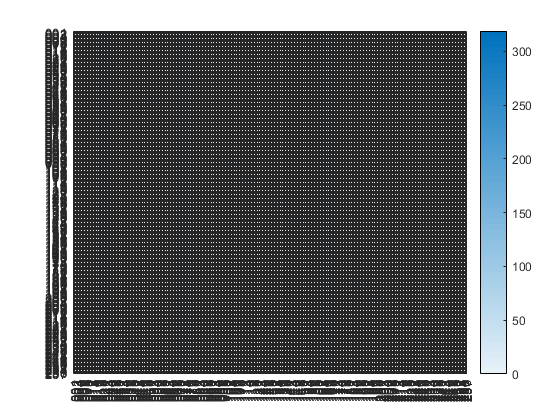

% view confusion matrix
[confmat, order] = confusionmat(truetest,preds);    
heatmap(order,order,confmat);

function Iout = readAndPreprocessImage2(filename)

        I = imread(filename);

        % Some images may be grayscale. Replicate the image 3 times to
        % create an RGB image.
        if ismatrix(I)
            I = cat(3,I,I,I);
        end

        % Resize the image as required for Alexnet.
        Iout = imresize(I, [224 224]);

        % Note that the aspect ratio is not preserved. In Caltech 101, the
        % object of interest is centered in the image and occupies a
        % majority of the image scene. Therefore, preserving the aspect
        % ratio is not critical. However, for other data sets, it may prove
        % beneficial to preserve the aspect ratio of the original image
        % when resizing.
end